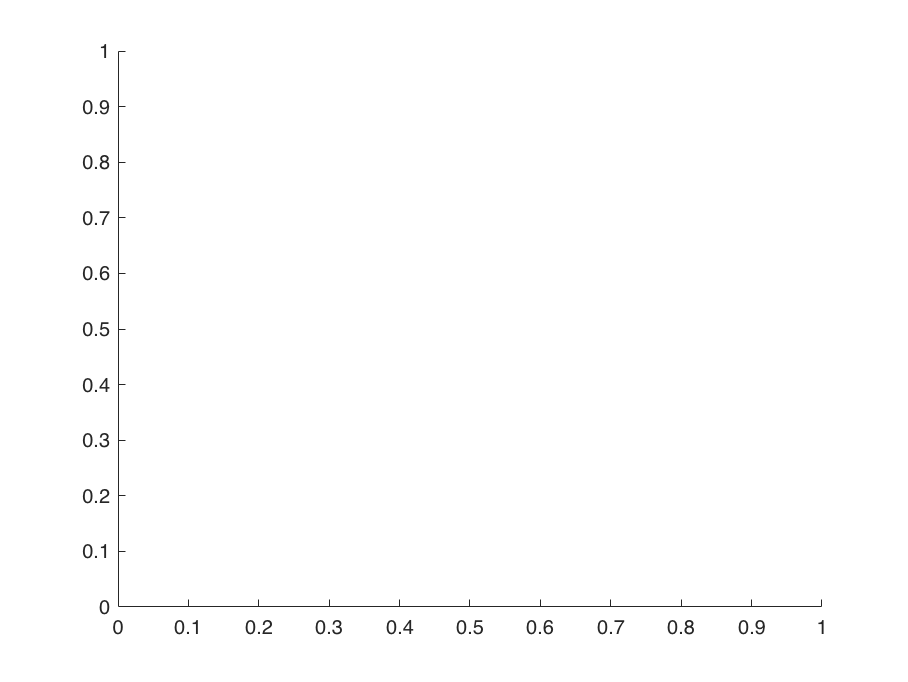

clear all
clc
figure(1)
hold on
figure(2)
hold on

f_max = 40;
theta_0 = 0;
A = 1;
K = 8;
B = (f_max - A)/exp(K);
a = 6.34;
b = 10;
c = 0.5;
beta = 0.8;
lambda_0 = 10^(-3);
tau = 10;


theta = [-180:6:179].*2*pi/360;


w_all = [];

for i = -180:6:179
    
    theta_0 = i*2*pi/360;
    f_vals = tuning_curve(A,B,K,theta_0,theta);
    u_vals = inv_sigmoid(a,b,c,beta,f_vals);    
    fft_f = fft(f_vals);
    fft_u = fft(u_vals);
    fft_f_squared = abs(fft_f).^2;
    lambda = lambda_0 * max(fft_f_squared);
    
    fft_w = (fft_u .* fft_f)./(lambda + fft_f_squared);
    w = ifft(fft_w);
    w = [w(i/6 + 30 +1:60),w(1:30 + i/6)];

    w_all = [w_all;w];

end
%% 

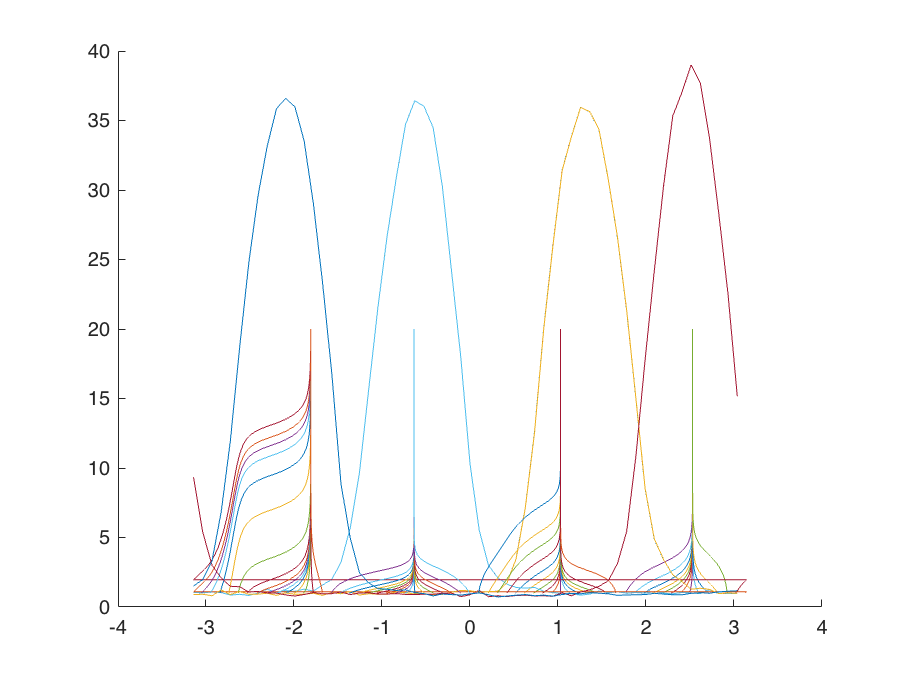


epsilon = 0.06;
stdev = mean(abs(w));
r = normrnd(0,stdev,60,60);
w_all_noisy = w_all + epsilon .* r;
final_states = [];
initial_states = [];
stable_states = [];
%% 

rng(2,'multFibonacci')
f_ini = abs(rand(60,1)); 
x = -10:1:-1;
p = 300.*normpdf(x,-5,2);

for i = 1:60
    if i > 51
        f_ini(i:60) = p(1:60-i+1);
        f_ini(1:10 - (60-i)-1) = p(60-i+2:10);
    
    else
        f_ini(i:i+9) = p;
    end
    initial_states = [initial_states ; f_ini];
    u_ini = inv_sigmoid(a,b,c,beta,f_ini);
    t_span = linspace(0,1000,1001);
    [t,u] = ode45(@(t,u) diff_eqn(t,u,a,b,c,beta,w_all,tau) , t_span, u_ini);
    f = sigmoid(a,b,c,beta,u);
    f1 = f(1001,:);
    stable_states = [stable_states ; f1];

    u_ini = inv_sigmoid(a,b,c,beta,f1);
    t_span = linspace(0,20000,5001);
    [t,u] = ode45(@(t,u) diff_eqn(t,u,a,b,c,beta,w_all_noisy,tau) , t_span, u_ini);
    f = sigmoid(a,b,c,beta,u);
    f1 = f(5001,:);
    final_states = [final_states ; f1];
    
    c_theta = cos(theta+pi).';
    s_theta = sin(theta+pi).';
    M_sum = sum(f,2);
    xi_bar = f*c_theta./M_sum;
    zeta_bar = f*s_theta./M_sum;
    theta_max= atan2(-zeta_bar,-xi_bar)+pi;
    idx = theta_max > pi;
    theta_max(idx) = theta_max(idx) - 2*pi;

    figure(1);
    plot(theta_max,linspace(1,20,5001));
    
    figure(2);
    plot(theta,f1);
    
end

%% 

% u_ini = inv_sigmoid(a,b,c,beta,f1);
% t_span = linspace(0,1000000,1000001);
% [t,u] = ode45(@(t,u) diff_eqn(t,u,a,b,c,beta,w_all_noisy,tau) , t_span, u_ini);
% f = sigmoid(a,b,c,beta,u);
% f1 = f(1000001,:);
% plot(theta,f1)